clear, clc

## COV THRESHOLD LINEAR APPROXIMATION

MVCs = 10:10:70;
optThres = [0.27 0.24 0.26 0.27 0.29 0.37 0.31];
slope = 0.0015;
optThres2 = [0.30 0.36 0.39 0.42 0.41 0.52 0.54];
slope2 = 0.0038;

figure, clf
subplot(1,2,1), hold on
plot(MVCs,optThres,'.-','MarkerSize',20)
plot(MVCs,slope*MVCs+0.3,'.-','MarkerSize',20)
xticks(0:10:70)
xticklabels({'','10% MVC','20% MVC','30% MVC','40% MVC','50% MVC','60% MVC','70% MVC'});
ylabel('Correlation Coefficient Threshold')
xlim([5,70])
legend({'Optimal Values','Approximation'},'Location','northwest')
title('Linear Approximation for QC With ISI Boundaries')
subplot(1,2,2), hold on
plot(MVCs,optThres2,'.-','MarkerSize',20)
plot(MVCs,slope2*MVCs+0.3,'.-','MarkerSize',20)
xticks(0:10:70)
xticklabels({'','10% MVC','20% MVC','30% MVC','40% MVC','50% MVC','60% MVC','70% MVC'});
ylabel('Correlation Coefficient Threshold')
xlim([5,70])
legend({'Optimal Values','Approximation'},'Location','northwest')
title('Linear Approximation for QC Without ISI Boundaries')
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 0.5]);

## LOAD DATA 

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Trial Information';
for MVC = 10:10:70
    names{MVC/10} = [num2str(MVC) '_MVC_with_BISI'];
    names2{MVC/10} = [num2str(MVC) '_MVC_no_BISI'];
end
for i = 1:7
    data(i) = load([path '\' names{i} '.mat']);
    data2(i) = load([path '\' names2{i} '.mat']);
end
clear path, clear names, clear names2, clear i, clear MVC

## PULSE TO NOISE RATIO

for MVC = 1:7
    for t_n = 1:5
        trialPNRs(MVC,t_n) = length(data(MVC).Trial(t_n).PNR_vec);
    end
end
x1 = NaN(max(trialPNRs(:)),35);
for MVC = 1:7
    for t_n = 1:5
        x1(1:trialPNRs(MVC,t_n),(5*(MVC-1)+t_n)) = data(MVC).Trial(t_n).PNR_vec';
    end
end
x = cell(1,5);
for trial = 1:5
    x{trial} = x1(:,trial:5:35);
end
figure, clf, hold on
boxplotGroup(x,'PrimaryLabels',{'1','2','3','4','5',},'SecondaryLabels',...
    {'10% MVC','20% MVC','30% MVC','40% MVC','50% MVC','60% MVC','70% MVC'},'GroupLabelType','Vertical')
ylabel('Pulse to Noise Ratio (PNR)')
xlabel('Trial number (#)')
title(['PNR Comparison Between all Trials of all MVCs'])
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1.5, 1]);

## CORRELATION COMPARISON

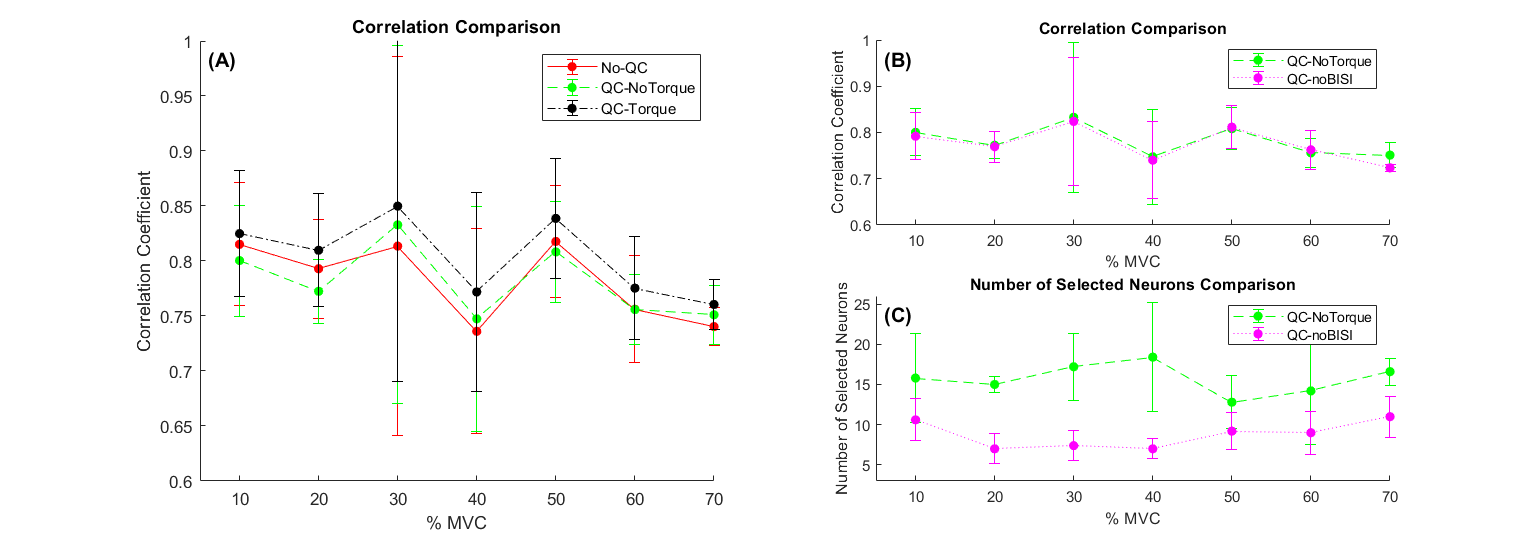

for trial = 1:3
    for MVC = 1:7
        Corr_mean1(trial,MVC) = mean(data(MVC).corr_coef(:,trial));
        Corr_std1(trial,MVC) = std(data(MVC).corr_coef(:,trial));
    end
end
for MVC = 1:7
    Corr_mean(1,MVC) = mean(data(MVC).corr_coef(:,2));
    Corr_std(1,MVC) = std(data(MVC).corr_coef(:,2));
    Corr_mean(2,MVC) = mean(data2(MVC).corr_coef(:,2));
    Corr_std(2,MVC) = std(data2(MVC).corr_coef(:,2));
    for trial = 1:5
        numNeurons(trial) = length(data(MVC).Trial(trial).QCids.Selected);
        numNeurons2(trial) = length(data2(MVC).Trial(trial).QCids.Selected);
    end
    NSN_mean(1,MVC) = mean(numNeurons);
    NSN_std(1,MVC) = std(numNeurons);
    NSN_mean(2,MVC) = mean(numNeurons2);
    NSN_std(2,MVC) = std(numNeurons2);
end
figure, clf
subplot(2,2,[1,3]), hold on %%
errorbar(Corr_mean1(1,:),Corr_std1(1,:),'-ro','MarkerSize',5,'MarkerEdgeColor','red','MarkerFaceColor','red')
errorbar(Corr_mean1(2,:),Corr_std1(2,:),'--go','MarkerSize',5,'MarkerEdgeColor','green','MarkerFaceColor','green')
errorbar(Corr_mean1(3,:),Corr_std1(3,:),'-.ko','MarkerSize',5,'MarkerEdgeColor','black','MarkerFaceColor','black')
xticks(0:7)
xticklabels({'','10','20','30','40','50','60','70'});
xlabel('% MVC')
ylabel('Correlation Coefficient')
ylim([0.6,1])
xlim([0.5,7])
legend({'No-QC','QC-NoTorque','QC-Torque'})
title('Correlation Comparison')
subplot(2,2,2), hold on %%
errorbar(Corr_mean(1,:),Corr_std(1,:),'--go','MarkerSize',5,'MarkerEdgeColor','green','MarkerFaceColor','green')
errorbar(Corr_mean(2,:),Corr_std(2,:),':mo','MarkerSize',5,'MarkerEdgeColor','magenta','MarkerFaceColor','magenta')
xticks(0:7)
xticklabels({'','10','20','30','40','50','60','70'});
xlabel('% MVC')
ylabel('Correlation Coefficient')
ylim([0.6,1])
xlim([0.5,7])
legend({'QC-NoTorque','QC-noBISI'})
title('Correlation Comparison')
subplot(2,2,4), hold on %%
errorbar(NSN_mean(1,:),NSN_std(1,:),'--go','MarkerSize',5,'MarkerEdgeColor','green','MarkerFaceColor','green')
errorbar(NSN_mean(2,:),NSN_std(2,:),':mo','MarkerSize',5,'MarkerEdgeColor','magenta','MarkerFaceColor','magenta')
xticks(0:7)
xticklabels({'','10','20','30','40','50','60','70'});
xlabel('% MVC')
ylabel('Number of Selected Neurons')
ylim([3,26])
xlim([0.5,7])
legend({'QC-NoTorque','QC-noBISI'})
title('Number of Selected Neurons Comparison')
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 0.8, 0.5]);
AddLetters2Plots(gcf, 'HShift', 0, 'VShift', 0, 'Direction', 'TopDown')

## PLOT THE SELECTED NEURONS

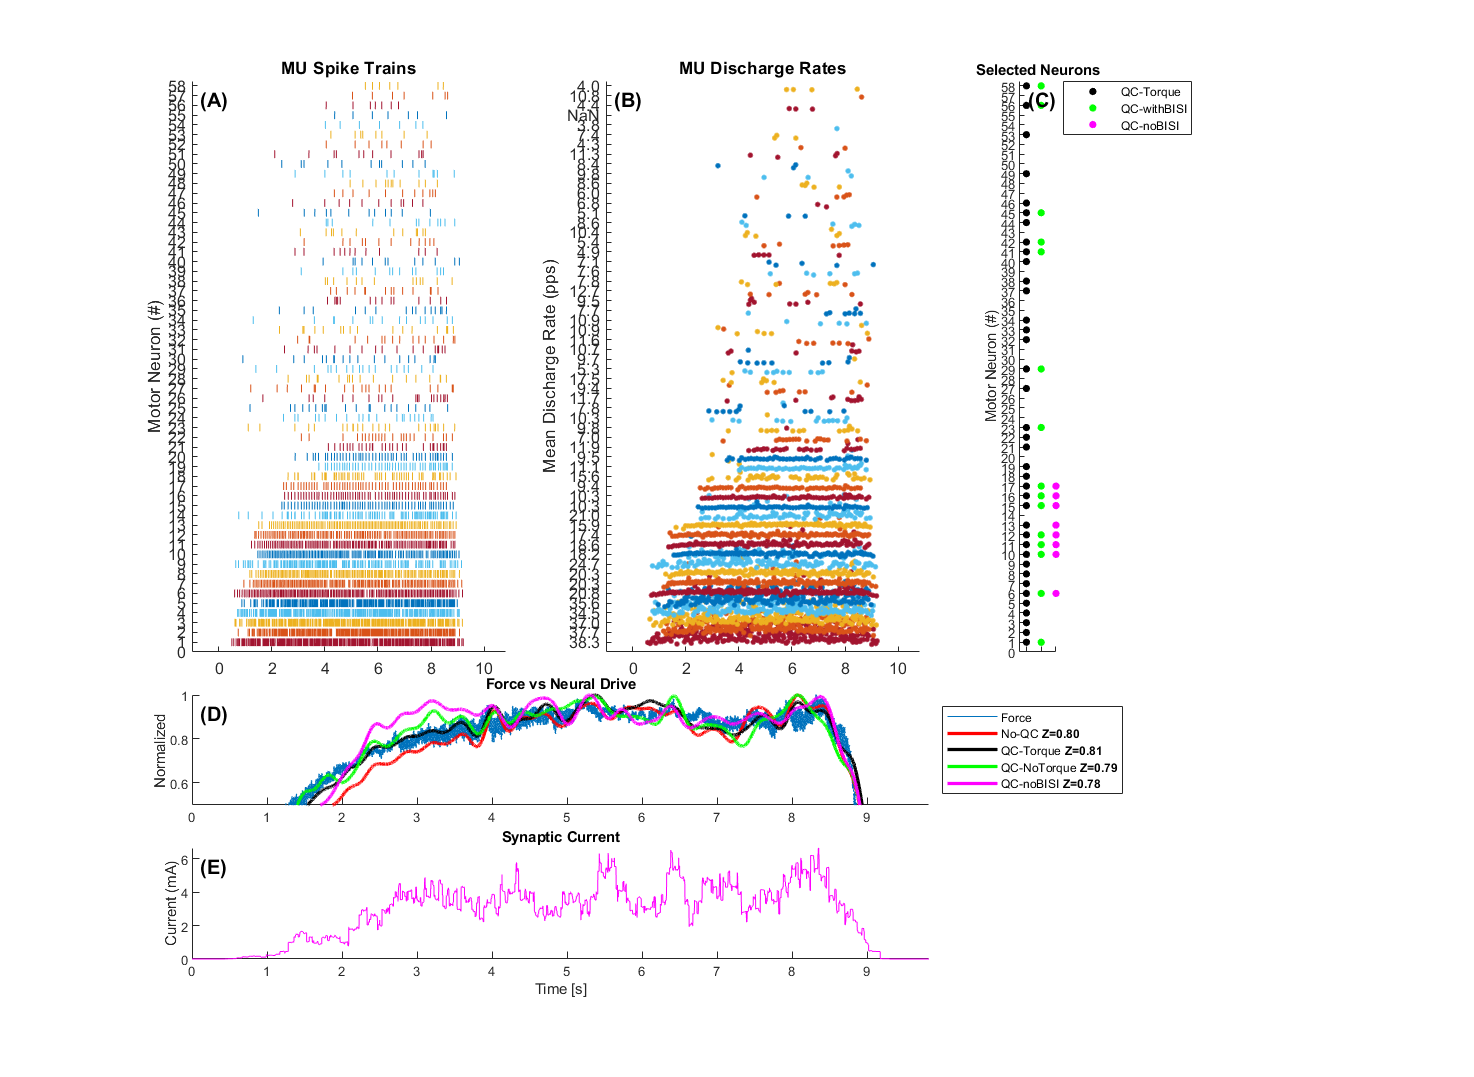

timecor = [0.7 0.4 0.7;
    1.2 0.6 0.8;
    1.4 0.7 1.1;
    1.2 0.4 0.7;
    0.7 1.2 1.4;
    1.2 0.6 0.7;
    1.4 1.2 1.1];
MVCs = 2;
TRIAL = 2;
for MVC = MVCs
    for trial = TRIAL
        %% Collent data
        % just colors
        color = {'#A2142F','#D95319','#EDB120','#4DBEEE','#0072BD'};
        linWidth = 0.5;
        colSeq = 1;
        % Selected neurons
        SelNeurons = data(MVC).Trial_corr(trial).QCids.Selected;
        SelNeurons2 = data(MVC).Trial(trial).QCids.Selected;
        SelNeurons3 = data2(MVC).Trial(trial).QCids.Selected;
        % get discarges
        dischargeRates = NaN(length(data(MVC).Trial(trial).tVec),length(data(MVC).Trial(trial).MUPulses_vec));
        for muCount = 1:length(data(MVC).Trial(trial).MUPulses_vec)
            dischargeRates(data(MVC).Trial(trial).MUPulses_vec{muCount}(2:end),muCount) = data(MVC).Trial(trial).fs./diff(data(MVC).Trial(trial).MUPulses_vec{muCount});
            % values below 3 hz may be due to big pauses (non physiological)
            dischargeRates(dischargeRates < 3 | dischargeRates > 100) = NaN;
        end
        averageDR = nanmean(dischargeRates);
        stdDR = nanstd(dischargeRates);
        
        %% Star Plotting
        figure, clf
        
        %% Sublot 1 & 2
        for muCount = 1:length(data(MVC).Trial(trial).MUPulses_vec)
            t2 = repelem(data(MVC).Trial(trial).tVec,2);
            spikePos = (data(MVC).Trial(trial).MUPulses_vec{muCount})*2;
            plotVar = NaN(size(t2));
            if ~isempty(spikePos)
                plotVar(spikePos) = muCount-0.4;
                plotVar(spikePos+1) = muCount+0.4;
            end
            sbp1 = subplot(6,3,[1 4 7 10]); hold on
            plot(t2,plotVar,'-','Color',color{colSeq},'LineWidth',linWidth);
            sbp2 = subplot(6,3,[2 5 8 11]); hold on
            plot(data(MVC).Trial(trial).tVec,dischargeRates(:,muCount)/30+muCount-0.5,...
                '.','Color',color{colSeq},'MarkerSize',10);
            if colSeq < 5
                colSeq = colSeq + 1 ;
            else
                colSeq = 1;
            end
        end
        
        %% Sublot 3
        sbp3 = subplot(6,3,[3 6 9 12]); hold on
        if trial <= 3
            plot(ones(1,length(SelNeurons)),SelNeurons,'.k','MarkerSize',15)
        else
            plot(NaN,NaN,'.k','MarkerSize',15)
        end
        plot(2*ones(1,length(SelNeurons2)),SelNeurons2,'.g','MarkerSize',15)
        plot(3*ones(1,length(SelNeurons3)),SelNeurons3,'.m','MarkerSize',15)
        xticks(0:3)
        xticklabels({'','','',''});
        xlim([0.5,3])
        ylim([0 length(data(MVC).Trial(trial).MUPulses_vec)+0.5]);
        yticks(0:length(data(MVC).Trial(trial).MUPulses_vec))
        ylabel('Motor Neuron (#)')
        legend({'QC-Torque','QC-withBISI','QC-noBISI'},'Location','northeastoutside')
        title('Selected Neurons')
        sbp3.Position = [sbp3.Position([1 2]) 0.025 sbp3.Position(4)];
        
        %% Sublot 4
        sbp4 = subplot(6,3,[13 14 15]); hold on
        if trial <= 3
            plot(data(MVC).CST_and_Force{5,trial}-data(MVC).CST_and_Force{5,trial}(1)+timecor(MVC,trial),data(MVC).CST_and_Force{4,trial})
            plot(data(MVC).Trial(trial).tVec,data(MVC).CST_and_Force{1,trial},'r','Linewidth',2)
            plot(data(MVC).Trial(trial).tVec,data(MVC).CST_and_Force{3,trial},'k','Linewidth',2)
            plot(data(MVC).Trial(trial).tVec,data(MVC).CST_and_Force{2,trial},'g','Linewidth',2)
            plot(data(MVC).Trial(trial).tVec,data2(MVC).CST_and_Force{2,trial},'m','Linewidth',2)
            names{1} = 'Force';
            names{2} = ['No-QC \bfZ=' num2str(data(MVC).corr_coef(trial,1),'%.2f')];
            names{3} = ['QC-Torque \bfZ=' num2str(data(MVC).corr_coef(trial,3),'%.2f')];
            names{4} = ['QC-NoTorque \bfZ=' num2str(data(MVC).corr_coef(trial,2),'%.2f')];
            names{5} = ['QC-noBISI \bfZ=' num2str(data2(MVC).corr_coef(trial,2),'%.2f')];
            legend(names,'Location','eastoutside','Orientation','vertical');
        end
        ylabel('Normalized')
        title('Force vs Neural Drive')
        xlim([data(MVC).Trial(trial).tVec(1),data(MVC).Trial(trial).tVec(end)])
        ylim([0.5,1])
        sbp4.Position = [sbp4.Position([1 2]) 0.5 sbp4.Position(4)];
        
        %% Sublot 5
        sbp5 = subplot(6,3,[16 17 18]); hold on
        plot(data(MVC).Trial(trial).tVec,data(MVC).Current{1,trial},'m')
        xlim([data(MVC).Trial(trial).tVec(1),data(MVC).Trial(trial).tVec(end)])
        xlabel('Time [s]')
        ylabel('Motor Neuron (#)')
        ylabel('Current (mA)')
        title('Synaptic Current')
        sbp5.Position = [sbp5.Position([1 2]) 0.5 sbp5.Position(4)];
        
        %% Add labels and more
        % sub 1
        subplot(6,3,[1 4 7 10])
        xlim([-1, max(data(MVC).Trial(trial).tVec)+1]);
        ylim([0 length(data(MVC).Trial(trial).MUPulses_vec)+0.5]);
        yticks(0:length(data(MVC).Trial(trial).MUPulses_vec))
        ylabel('Motor Neuron (#)')
        title('MU Spike Trains')
        % sub 2
        subplot(6,3,[2 5 8 11])
        xlim([-1, max(data(MVC).Trial(trial).tVec)+1]);
        ylim([0 length(data(MVC).Trial(trial).MUPulses_vec)+0.5]);
        yticks(0:length(data(MVC).Trial(trial).MUPulses_vec))
        yticklabels({'',num2str(averageDR(:),'%.1f')});
        ylabel('Mean Discharge Rate (pps)')
        title('MU Discharge Rates')
        
        % plot final params
        set(gcf, 'units', 'normalized');
        set(gcf, 'Position', [0, 0, 1, 1.3]);
        AddLetters2Plots(gcf, 'HShift', 0, 'VShift', 0, 'Direction', 'LeftRight')
    end
end

## COMPARE THE TOTAL NUMBER OF AVAILABLE NEURONS

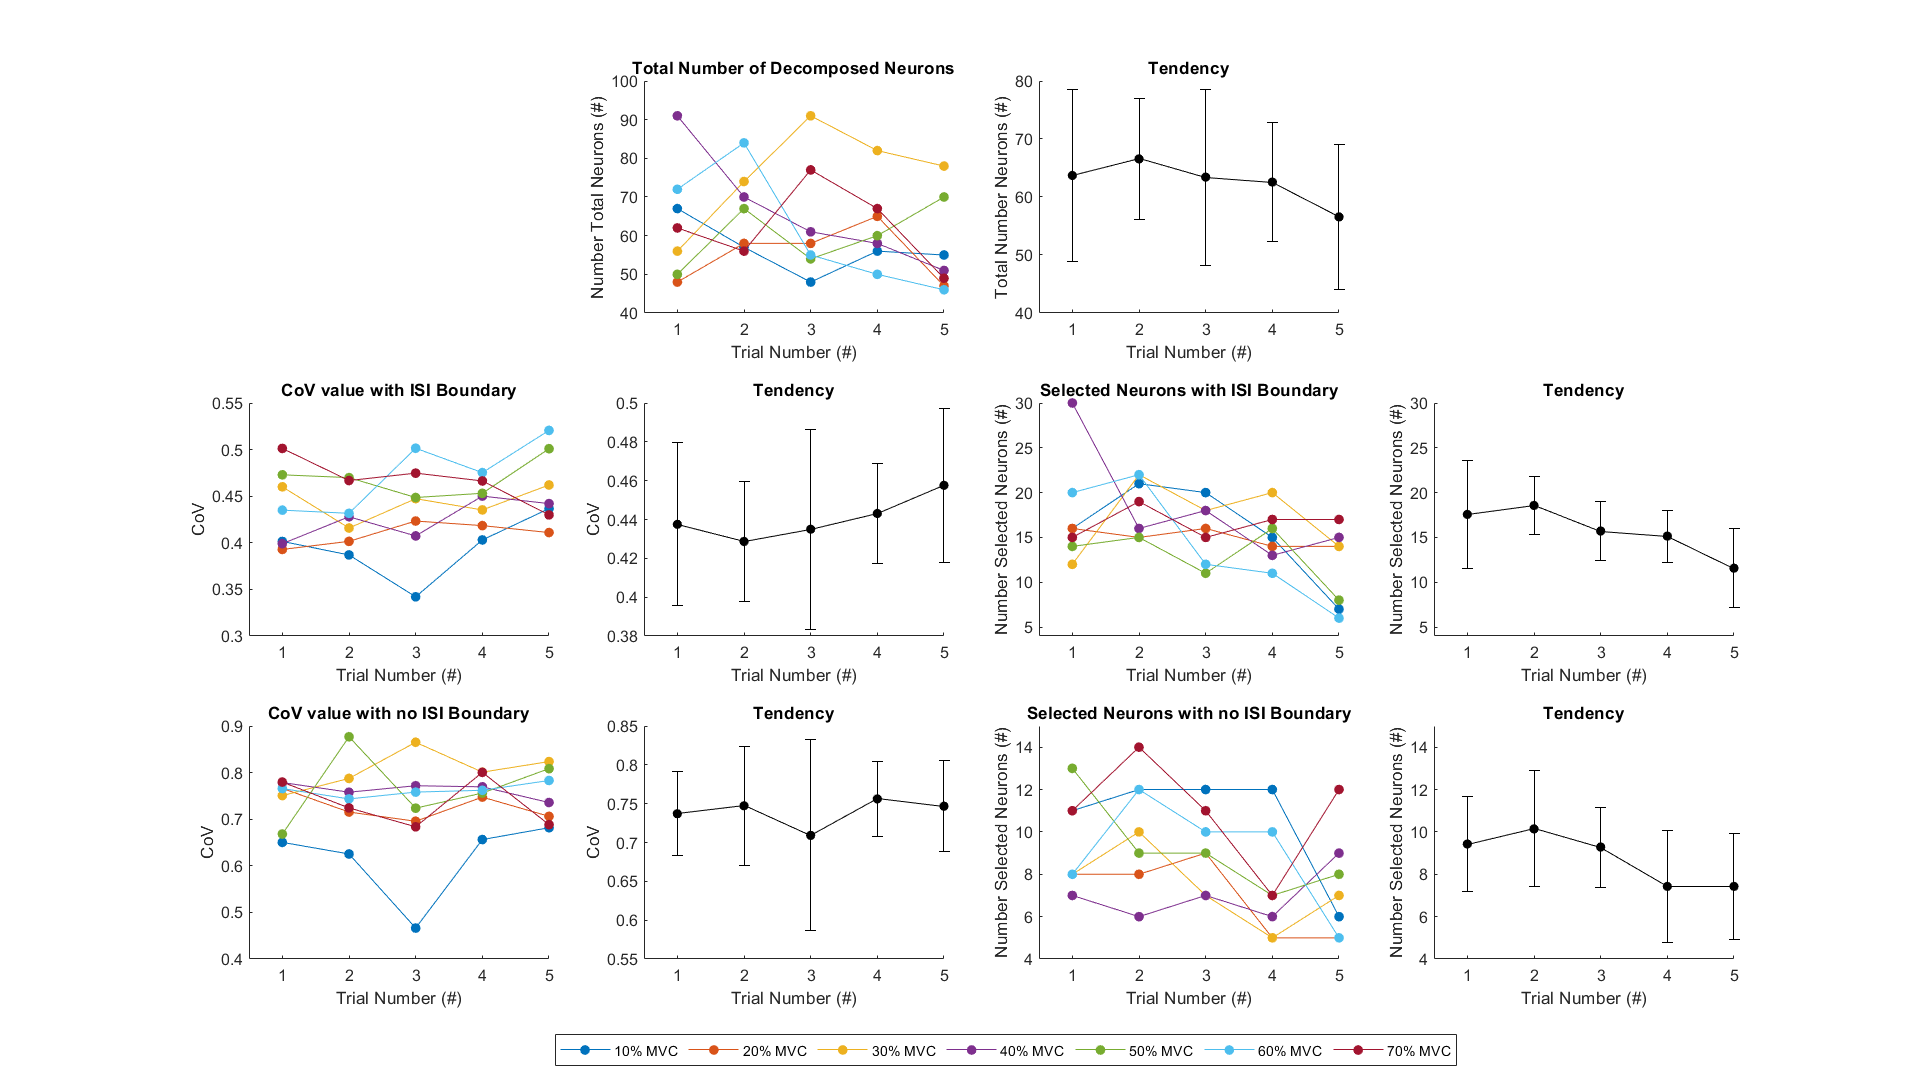

% subplots
rs = 3;
cols = 4;

figure, clf
subplot(rs,cols,2), hold on
for MVC = 1:7
    for trial = 1:5
        numNeurons(MVC,trial) = length(data(MVC).Trial(trial).MUPulses_vec);
    end
    plot(numNeurons(MVC,:),'.-','MarkerSize',20)
end
xticks(0:5)
ylabel('Number Total Neurons (#)')
xlim([0.5,5])
xlabel('Trial Number (#)')
lg = legend({'10% MVC','20% MVC','30% MVC','40% MVC','50% MVC','60% MVC','70% MVC'},'Orientation','horizontal');
title('Total Number of Decomposed Neurons')

subplot(rs,cols,3), hold on
errorbar(mean(numNeurons),std(numNeurons),'-ko','MarkerSize',5,'MarkerEdgeColor','black','MarkerFaceColor','black')
xticks(0:5)
ylabel('Total Number Neurons (#)')
xlim([0.5,5])
xlabel('Trial Number (#)')
title('Tendency')

subplot(rs,cols,5), hold on
for MVC = 1:7
    for trial = 1:5
        covValues(MVC,trial) = nanmean(data(MVC).Trial(trial).COV_ISI_vec);
    end
    plot(covValues(MVC,:),'.-','MarkerSize',20)
end
xticks(0:5)
ylabel('CoV')
xlim([0.5,5])
xlabel('Trial Number (#)')
title('CoV value with ISI Boundary')

subplot(rs,cols,6), hold on
errorbar(mean(covValues),std(covValues),'-ko','MarkerSize',5,'MarkerEdgeColor','black','MarkerFaceColor','black')
xticks(0:5)
ylabel('CoV')
xlim([0.5,5])
xlabel('Trial Number (#)')
title('Tendency')

subplot(rs,cols,9), hold on
for MVC = 1:7
    for trial = 1:5
        covValues2(MVC,trial) = nanmean(data2(MVC).Trial(trial).COV_ISI_vec);
    end
    plot(covValues2(MVC,:),'.-','MarkerSize',20)
end
xticks(0:5)
ylabel('CoV')
xlim([0.5,5])
xlabel('Trial Number (#)')
title('CoV value with no ISI Boundary')

subplot(rs,cols,10), hold on
errorbar(mean(covValues2),std(covValues2),'-ko','MarkerSize',5,'MarkerEdgeColor','black','MarkerFaceColor','black')
xticks(0:5)
ylabel('CoV')
xlim([0.5,5])
xlabel('Trial Number (#)')
title('Tendency')

subplot(rs,cols,7), hold on
for MVC = 1:7
    for trial = 1:5
        numNeurons(MVC,trial) = length(data(MVC).Trial(trial).QCids.Selected);
    end
    plot(numNeurons(MVC,:),'.-','MarkerSize',20)
end
xticks(0:5)
ylabel('Number Selected Neurons (#)')
xlim([0.5,5])
ylim([4,30])
xlabel('Trial Number (#)')
title('Selected Neurons with ISI Boundary')

subplot(rs,cols,8), hold on
errorbar(mean(numNeurons),std(numNeurons),'-ko','MarkerSize',5,'MarkerEdgeColor','black','MarkerFaceColor','black')
xticks(0:5)
ylabel('Number Selected Neurons (#)')
xlim([0.5,5])
ylim([4,30])
xlabel('Trial Number (#)')
title('Tendency')

subplot(rs,cols,11), hold on
for MVC = 1:7
    for trial = 1:5
        numNeurons2(MVC,trial) = length(data2(MVC).Trial(trial).QCids.Selected);
    end
    plot(numNeurons2(MVC,:),'.-','MarkerSize',20)
end
xticks(0:5)
ylabel('Number Selected Neurons (#)')
xlabel('Trial Number (#)')
xlim([0.5,5])
ylim([4,15])
title('Selected Neurons with no ISI Boundary')

subplot(rs,cols,12), hold on
errorbar(mean(numNeurons2),std(numNeurons2),'-ko','MarkerSize',5,'MarkerEdgeColor','black','MarkerFaceColor','black')
xticks(0:5)
ylabel('Number Selected Neurons (#)')
xlim([0.5,5])
ylim([4,15])
xlabel('Trial Number (#)')
title('Tendency')

set(lg,'Position', [0.5, 0.01, 0.05, 0.03],'units','normalized');
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 1]);